**a) Sparse Signals **

x = [(1:5)/5 zeros(1,128-5)];
x = x(randperm(128));
y = x + 0.05*randn(1,128);

Show that $\min \left(\frac{1}{2}||\hat{x} -y||_2^2 +\lambda \frac{1}{2}||\hat{x} |{\left|\right.}_2^2 \right)$ has a close form solution: $\hat{x} =\frac{1}{1+\lambda \;}y$

By taking the first order derivative of the function above and setting the result to 0, we can find the minimum.

Firstly, if we fully express the L2 norm terms:


$$\frac{1}{2}\sum_{i=1}^n {\left(\hat{x_i } -y_i \right)}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n {\hat{x} }^2 =\left\lbrack \frac{1}{2}{\left(\hat{x_1 } -y_1 \right)}^2 +\frac{\lambda }{2}{\hat{\left(x_1 \right)} }^2 \right\rbrack +\left\lbrack \frac{1}{2}{\left({\hat{x} }_2 -y_2 \right)}^2 +\frac{\lambda }{2}\;{\left(\hat{x_2 } \right)}^2 \right\rbrack +\;\ldotp \ldotp \ldotp$$


and taking the derivative:


$$\frac{\partial }{\partial \hat{x} }\left(\frac{1}{2}\sum_{i=1}^n {\left(\hat{{\;x}_i } -y_i \right)}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n {\left(\hat{x_i } \right)}^2 \right)=\;\frac{1}{2}\left(\frac{\partial }{\partial \hat{x} }{\left({\hat{x} }_1 -y_1 \right)}^2 \right)+\frac{\lambda \;}{2}\left(\frac{\partial }{\partial \hat{x} }\left({x_1 }^2 \right)\right)+\;\ldotp \ldotp \ldotp \;\;$$

$$=\left(\hat{x_1 } -y_1 \right)\frac{\partial \left(\hat{x_1 } -y_1 \right)}{\partial \hat{x} }+\lambda \left({\hat{x} }_1 \right)\frac{\partial \left({\hat{x} }_1 \right)}{\partial \hat{x} }+\;\ldotp \ldotp \ldotp \;=\left(\hat{x_1 } -y_1 +\hat{{\;x}_2 } -y_2 +\;\ldotp \ldotp \ldotp \right)+\lambda \left({\hat{x} }_1 +{\;\hat{x} }_2 +\;\ldotp \ldotp \ldotp \right)$$
  

Thus:


$$\frac{\partial }{\partial \hat{x} }\left(\frac{1}{2}\sum_{i=1}^n |x_i -y_i {\left|\right.}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n \left|\hat{x_i } {\left|\right.}^{2\;} \right.\right)=\hat{x} -y+\lambda \hat{x} =0\;$$



$$\hat{x} +\lambda \hat{x} =y$$


        
$$\to \left\lbrack \hat{x} =\frac{y}{\left(1+\lambda \;\right)}\right\rbrack$$


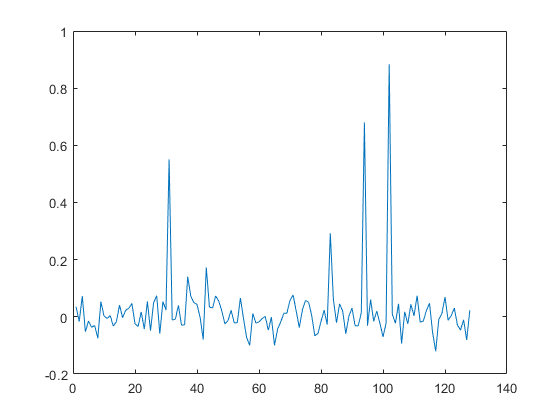

lambda = [0.01, 0.05, 0.1, 0.2];
figure; plot(y/(1+lambda(3)));

**b) Sparse Signals and the **$l^1$** Norm**

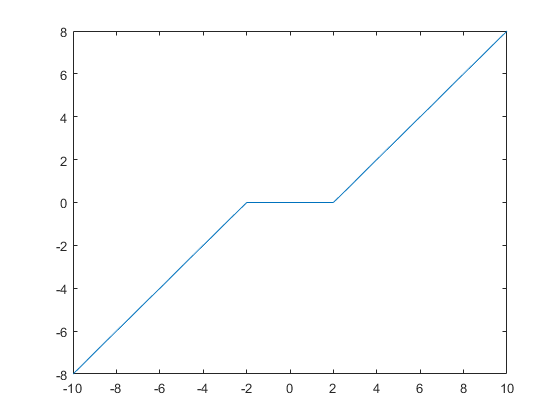

lambda_test = 2;
y_test = -10:0.1:10;
xhat_test = SoftThresh(y_test,lambda_test);
figure; plot(y_test, xhat_test);

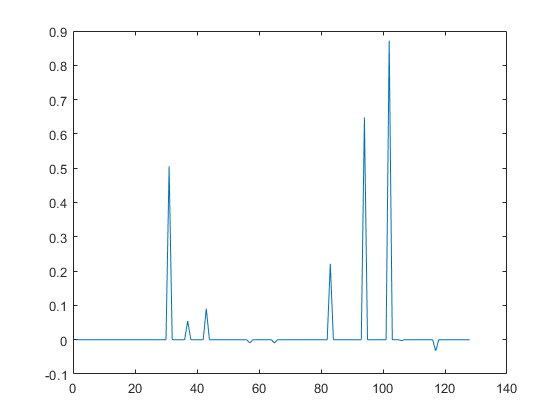

xhat = SoftThresh(y,lambda(3));
figure; plot(xhat)

**c) Random Frequency Domain Sampling and Aliasing**

X = fftc(x,2);
Xu = zeros(1,128);
Xu(1:4:128) = X(1:4:128);
xu = ifftc(Xu,2)*4;
figure; plot(abs(xu));



### Functions

function [xhat] = SoftThresh(y,lambda)

xhat = zeros(1,length(y));
for i=1:length(y)
    if y(i) < -lambda
        xhat(i) = y(i) + lambda;
    elseif abs(y(i)) <= lambda
        xhat(i) = 0;
    else
        xhat(i) = y(i) - lambda;
    end
end 

end